clc
clear all
close all

letter = "B";
directory = "Test Images/Snipped/"+letter+"/";
imagefiles = dir(directory);      
nfiles = length(imagefiles);    % Number of files found

% figure()
for ii=4:nfiles
   currentfilename = imagefiles(ii).name;
   currentimage = imread(directory+currentfilename);
   images{ii - 3} = currentimage;
   [~,imageNames{ii - 3},~] = fileparts(currentfilename);
   % subplot(nfiles-3, 1, ii - 3);
   % imshow(images{ii - 3});
end

% images{1} = imread("Test Images/Snipped/A/A4.jpg");
% images{2} = imread("Test Images/Snipped/A/A7.jpg");
% images{3} = imread("Test Images/Snipped/A/A15.jpg");
% images{4} = imread("Test Images/Snipped/A/A12.jpg");
% images{5} = imread("Test Images/Snipped/A/A18.jpg");

% images{1} = imread("leftoriginal.png")
% images{2} = imread("leftleft.png")

% % right = imread("leftshifted.png");
% figure()
% imshow(images{1})
% imshow(images{2})

out = images{1};
thresh = 0.005;
stitched = zeros(length(images),1);
stitched(1)=1;
length(images);
for j=1:length(images)
    disp(j)
    confidences = zeros(length(images),3);
    for i=1:length(images)
        if stitched(i)==0
            [final_slope, final_length, final_delta_x, final_delta_y, final_confidence] = custom_sift(out, images{i}, 8, true);
            confidences(i,:)=[final_confidence,final_delta_x,final_delta_y];
        end
    end
    if sum(confidences(:,1)>thresh)~=0
        [v,ind]=max(confidences(:,1));
        disp(v)
        stitched(ind)=1;
        out = merge_images(out, images{ind}, round(-confidences(ind,2)), round(-confidences(ind,3)));
        imwrite(out, "Output/"+letter+"/Run1_Stitch"+sum(stitched)+"_Conf"+round(v*10000)+".jpg")
    else
        break
    end
end

     1



    0.1374



     2



    0.2146



     3



    0.3504



     4



    0.1286



     5



    0.2704



     6



    0.0718



     7



    0.3073



     8



    0.0250



     9



    0.0065



    10



    0.2067



    11



    0.0331



    12



    0.1123



    13



    0.0084



    14



sum(stitched)

ans = 14

imageNames(~stitched)

ans = 1×6 cell array
    {'B16'}    {'B20'}    {'B3'}    {'B4'}    {'B8'}    {'B9'}


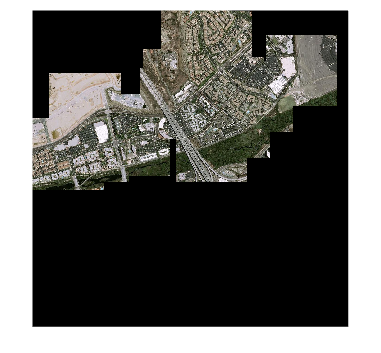

imshow(out);